clear all; clc; close all;
num_cargas = 200;
qroja = 1e-5;
qazul = -1e-5;
k = 9e+9;


largo_roja=3.5;
largo_azul=2.5;
d = 0.4;
t = 0.05;

figure;
hold on;
axis equal
grid on;

axis([-2 2 -2 2])







## Calculo de Campo

Se crea una linea de puntos de carga en el plano x,y 

Yp = linspace(-largo_roja/2, largo_roja/2, num_cargas);
Yn = linspace(-largo_azul/2, largo_azul/2, num_cargas);
Xq_roja = zeros(size(Yp)); 
Xq_azul = d * ones(size(Yn));




Se crea el campo en el eje Z 0 y se crea una malla en el plano x,y para calcular el campo

[X_obs, Y_obs] = meshgrid(-3:0.1:3, -3:0.1:3); 

Ex = zeros(size(X_obs));    
Ey = zeros(size(X_obs));     
V  = zeros(size(X_obs));     


Se hace un ciclo por todas las cargas en todos los puntos del plano donde calculamos el campo eléctrico y sumamos la superposicion de los campos de todas las cargas. Usamos la fórmula E = k * q * R/r^3 y evitamos la division entre 0.

for i = 1:num_cargas
    rx = X_obs - Xq_roja(i);
    ry = Y_obs - Yp(i);
    r = sqrt(rx.^2 + ry.^2);
    r(r < 0.05) = 0.05;
    
    Ex = Ex + (k * qroja/num_cargas) .* (rx ./ r.^3);
    Ey = Ey + (k * qroja/num_cargas) .* (ry ./ r.^3);
    V  = V  + (k * qroja/num_cargas) ./ r;

    rx = X_obs - Xq_azul(i);
    ry = Y_obs - Yn(i);
    r = sqrt(rx.^2 + ry.^2);
    r(r < 0.05) = 0.05;
    
    Ex = Ex + (k * qazul/num_cargas) .* (rx ./ r.^3);
    Ey = Ey + (k * qazul/num_cargas) .* (ry ./ r.^3);
    V  = V  + (k * qazul/num_cargas) ./ r;
end


Finalmente calculamos el vector resultantes y lo hacemos unitario para indicar la direccion de una manera visual y lo graficamos.

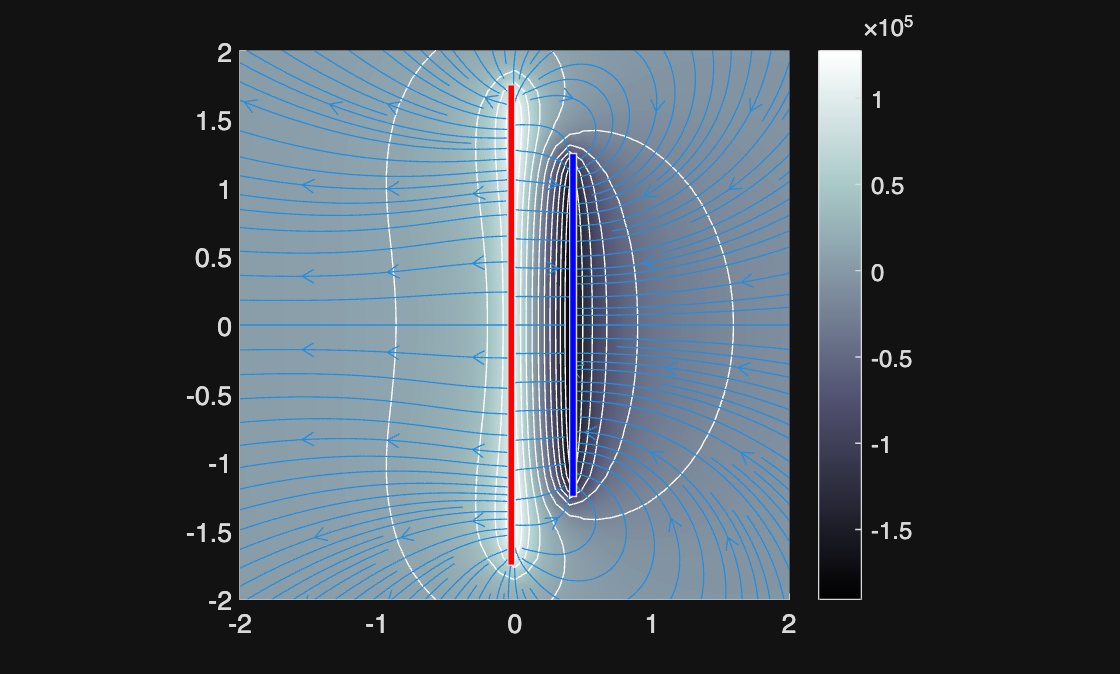

pcolor(X_obs, Y_obs, V)
colormap bone
shading interp;
colorbar

contour(X_obs, Y_obs, V, 10, '-w', 'LineWidth', 0.5); 
streamslice(X_obs, Y_obs, Ex, Ey, 2)
rectangle('Position',[d -largo_azul/2  t largo_azul], 'FaceColor','b')
rectangle('Position',[-t -largo_roja/2  t largo_roja],'FaceColor','r')
hold off;

parte 2

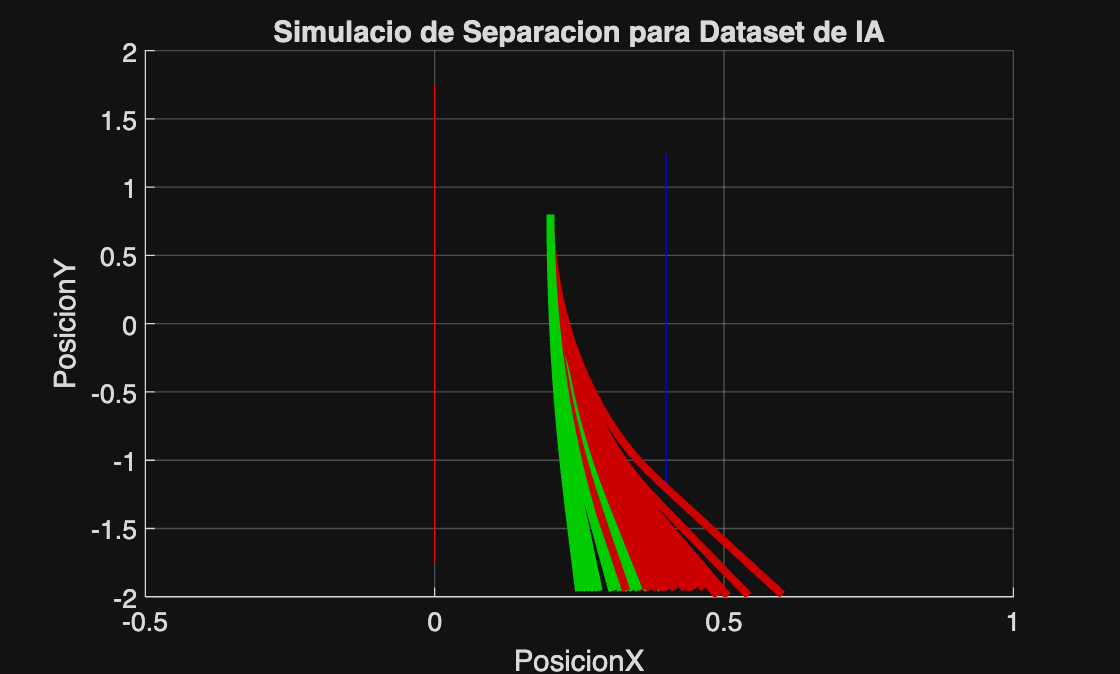

nq = 40; %Cantidad de globulos
dt = 0.02;
dataset = zeros(nq,6); %Carga, Masa, Tiempo, Vel_Max, X_final, Clase


figure(2);
ax_sim = axes;
hold(ax_sim, 'on');
title('Simulacio de Separacion para Dataset de IA')
xlabel('PosicionX'); ylabel('PosicionY');
grid on;
axis(ax_sim, [-0.5 1 -2 2]);
plot(Xq_roja, Yp, 'r', 'MarkerSize', 50);
plot(Xq_azul, Yn, 'b', 'MarkerSize', 50);

for q = 1:nq
    if rand()>0.5
        clase = 0; %Sano
        color = [0, 0.8, 0];
        qE_base = 0.8e-6;
        m = 1.0;
    else
        clase = 1; %Infectado
        color = [0.8,0,0];
        qE_base = 1.4e-6;
        vol_parasito = 0.1 + rand()*0.8;
        m = 1.0 + (vol_parasito * 0.2);
    end
    
    qE = qE_base + (randn()*0.25e-6);

    xe = .2; ye = 0.8;
    Vx= 0; Vy = -3;

    t_vuelo = 0;
    v_max = 0;
    
    path = animatedline("Color", color, "LineWidth",3);

    while ye >-2 && ye < 2 && xe >-2 && xe <2
        t_vuelo = t_vuelo + dt;
        addpoints(path,xe,ye)
        Fx = 0; Fy = 0;
        for i = 1:num_cargas
            rx = xe - Xq_azul(i); ry = ye - Yn(i);
            r = sqrt(rx^2 + ry^2);
            r(r < 0.05) = 0.05;
            Fx = Fx + (k * (qazul / num_cargas) * qE) * (rx / r^3);
            Fy = Fy + (k * (qazul / num_cargas) * qE) * (ry / r^3);

        end
       
        Vx = Vx + (Fx / m) * dt;
        Vy = Vy + (Fy / m) * dt;
        xe = xe + Vx * dt;
        ye = ye + Vy * dt;

        v_inst = sqrt(Vx^2 + Vy^2);
        if v_inst > v_max, vmax = v_inst; end
    
    end
    dataset(q,:) = [qE, m, t_vuelo, v_inst,xe,clase];
    drawnow limitrate
end

% headers = {'Carga', 'Masa', 'Tiempo', 'Velocidad', 'Posicion', 'Clase'};
% T = array2table(dataset, 'VariableNames', headers);
% writetable(T, 'datosCelulas.csv');
